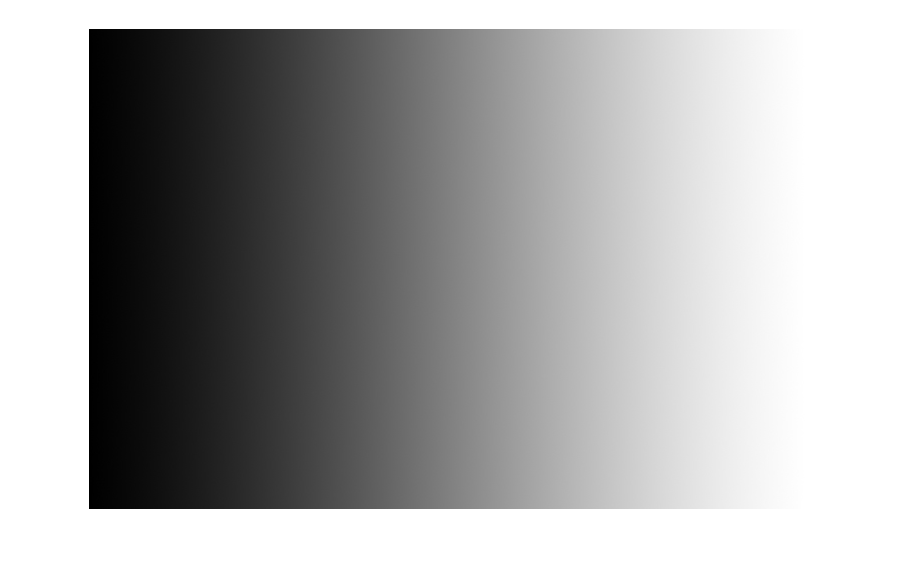

% original image
img = rgb2gray(imread("gramp.jpg"));
imshow(img)

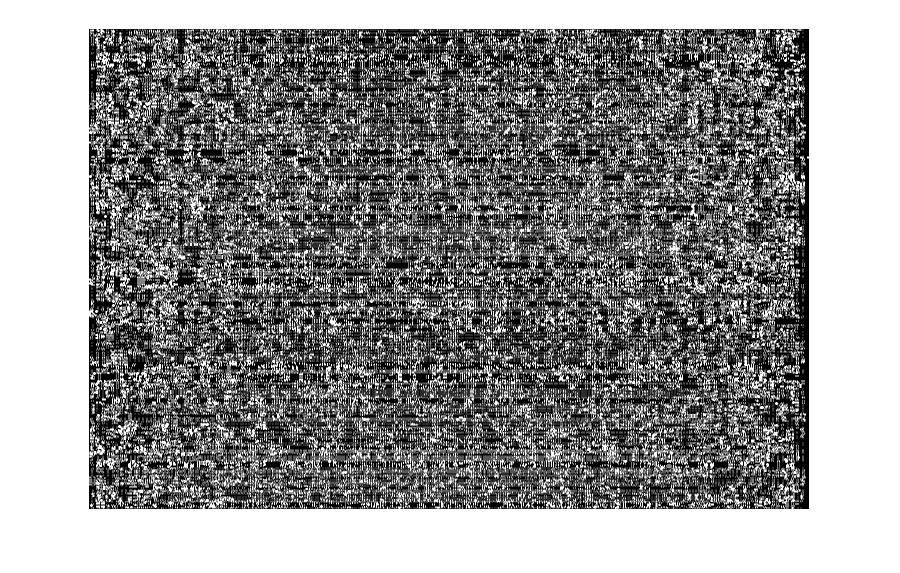

[m,n] = size(img);

% Cycles
B=256;

% for every row and every column
for x = 1:m
    img(x, :) = spatialfreq1D(img(x, :), B);
end
for y = 1:n
    img(:, y) = spatialfreq1D(img(:, y), B);
end

% final result
imshow(img)

function ret = spatialfreq1D(img, B)

    % pad image vector by one on each side
    img_padded = zeros(1, length(img)+2);
    for i = 1:length(img)
        img_padded(i+1) = img(i);
    end
    img_padded(1) = img_padded(2);
    img_padded(length(img_padded)) = img_padded(length(img_padded)-1);
    
    % find the difference between the vector data
    difference = zeros(1, length(img)+1);
    for i = 1:length(img)+1
        difference(i) = abs(img_padded(i+1) - img_padded(i));
    end
    
    % add the differences from the left and right neighbors
    combined_differences = zeros(1, length(img));
    for i = 1:length(img)
        combined_differences(i) = difference(i+1) + difference(i);
    end
    
    % create a look-up table to boost high value and suppress low values.
    % Center LUT at B/2 - 1 
    LUTi = 0:B-1;
    LUTo = LUTi - B/2 + 1;
%     stem(LUTi, LUTo);
    
    % compare the original image to the LUT
    new_value = zeros(1, length(img));
    for i = 1:length(img)
        if (combined_differences(i) < 1)
            new_value(i) = LUTo(1);
        elseif (combined_differences(i) > 256)
            new_value(i) = LUTo(256);
        else
            new_value(i) = LUTo(combined_differences(i))+1;
        end
    end
    
    % Normalize to move data which is negative or too large. Round to
    % remove floats
    normalizedData = normalize(new_value,"range",[0,B-1]);
    ret = round(normalizedData);
end